# Lab:  Up and Down-Conversion (Undergraduate version)

Communication systems typically process signals in *complex baseband *and transmit and receive the signals in *radio frequency (RF).*  The complex baseband signal is also called *baseband IQ*.  Up and down-conversion is  the basic mechanism by which the systems convert between the two domains.  Typically, the up and down-conversion is performed in analog.  In this lab, we will simulate the process digitally and then use an SDR to perform the up and down-conversion.  The SDR performs the up and down-conversion in analog, and we will simply observe the results.  

A simple block diagram for a typical up and conversion system is shown in the figure below.  The complex baseband TX is up-converted to an RF signal and then fed through a power amplifier (PA) before it is transmitted.  At the receiver, the received RF signal is passed through a low noise amplifier (LNA) and then mixed and filtered to obtain the complex baseband RF.  

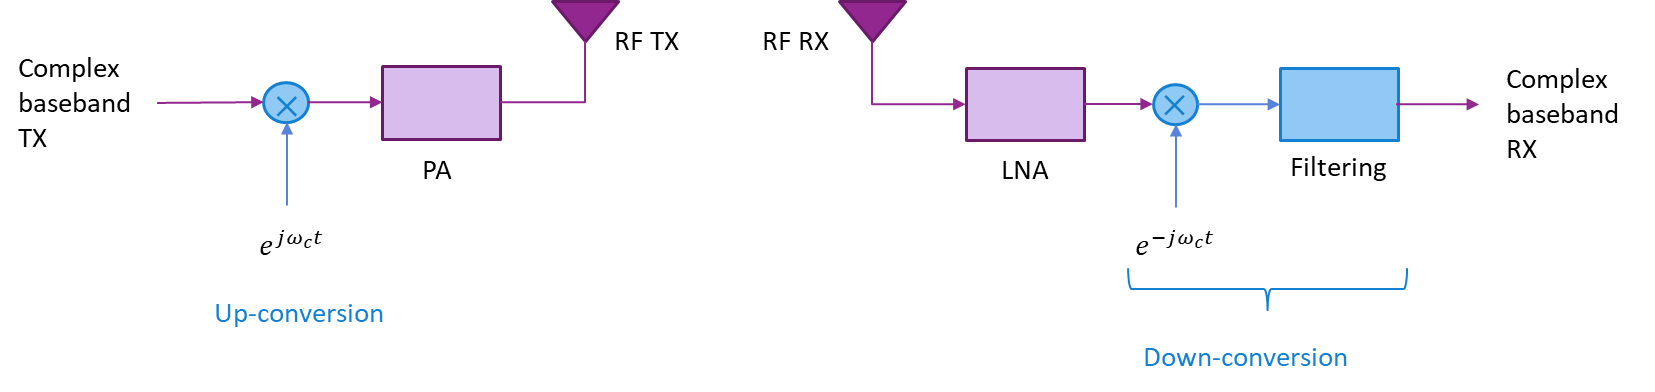

In this lab, you will learn how to: 

- Create a simple complex baseband signal

- Simulate upconversion and downconversion

- Simulate a simple passband filter

- Visualize the effects of downconversion.

- Perform the up and down-conversion on an SDR

**Instructions**: Complete all the sections labeled `%TODO`. In the last subsection you need to write your observations for the above sections. When you finish, run the to create a PDF. Submit the PDF in Gradescope. Do not submit the MATLAB files.

## Creating A Simple Complex Baseband Signal

To illustrate the concepts, we will create a simple complex baseband signal (also called the *baseband IQ*):

where the in-phase and quadrature components, x`i `and x`q,` are the rectangular and triangular pulses, respectively:

where `wid` is the pulse width.  We will first create sampled versions of these signals at the sample rate `fsamp` below.  

To create the rectangular and triangular pulses, you can use the `rectpuls` and `tripuls` commands in MATLAB.

fsamp = 10e6;     % Sample rate in Hz
nsamp = 4096;
t = (-nsamp/2+1:nsamp/2)'/fsamp;  % Time range
wid = 100e-6;      % pulse width

% TODO:  Create vectors, xi and xq, of the samples of the signals at the
% times in the vector t.  
%    xi = rectpuls(...);
%    xq = tripuls(...);

Create the complex baseband signal x`(t) = xi(t) + j*xq(t)`.   Remember that in MATLAB, the imaginary number `j` is represented by `1i`.  So you can use x` = xi + 1i*xq`.  

% TODO:  
%   x = ...

## Visualize the Signal in Time-Domain

To visualize the time-domain signals, plot xi(t) vs. t and xq(t) vs. t.  To make the plot visually easy to read:

- Plot the two signals on one plot

- Plot the time axis in micro-seconds

- Label the time axis

- Create a legend indicating which curves are for xi(t) and xq(t) using the `legend` command

- Add grid lines with the `grid on` command

% TODO:
%   tus = ...;  % Time in us
%   plot(...);
%   legend(...);
%   grid on;

## Visualize the Baseband Signal in Frequency-domain

Following the [frequency offset lab](matlab:open('../lab_freq/freqUG.mlx')), compute the normalized, circularly shifted FFT, `Xf`, the frequencies, `f`, and the power spectrum density, `Xfpow`.  Plot `Xfpow` vs the frequency in MHz.  

%  TODO:
%   Xf = ...
%   f = ...
%   fMHz = ...
%   Xfpow = ...

%  TODO:  Plot the PSD


## Upconvert the Baseband Signal

Upconversion creates real passband signal for a carrier frequency `fc` given by:

The signal envelope is:

In actual systems, the real passband signal is typically created in analog by first running the complex baseband signal through an digital-to-analog converter (DAC) and then using an analog circuit to perform the multiplication by exp(2*pi*1i*t*fc) (called* mixing*).  Here, we will simulate the mixing digitally assuming a low carrier frequency.  

fc = 0.5e6;  % Carrier frequency

% TODO:  Calcalate the real passband signal, xp, and its envelope, xenv.
%   xp = ...
%   xenv = ...


Now plot `xp(t) vs. t.`   On the same plot, plot the envelope `xenv(t)` and `-xenv(t)` vs. t.  Plot the time in microseconds.  You should see that the real passband signal varies rapidly between `-xenv(t) and xenv(t).  `

clf;

% TODO:
%   plot(...);


To view the oscilations of the real passband signal more clearly, replot the signal as before for `t` in -50 us to 50 us.

% TODO


## Visualize the Baseband and Passband Signals in Frequency Domain.

Now, similar to the way we computed `Xfpow` from `x`, compute the PSD `Xpfpow` from `xp`.  Plot `Xfpow` and `Xpfpow` vs. f on the same graph.  Use the same y-axis limits as before.  You should see that the passband modulation shifted the frequency response by `fc`.

% TODO:  
%   Xpf = ..
%   Xpfpow = ...
%   plot(...)


## Downconvert the Signal

We will now simulate the down-conversion.  Again, this is normally done in analog, but here we simulate the down-conversion digitally.  From class, the down-conversion is in two steps:

- Mix the signal:  v = 2*exp(-2*pi*1i*t*fc).*xp;

- Filter the signal:   y = conv(v,h,'same')

We will need to first construct the low pass filter, `h`.  MATLAB has several excellent filter design functions.  Here, we will just use the simple function `fir1.  `

nfilt = 40;
fp = fc/fsamp/2;
h = fir1(nfilt, fp, 'low')';


Now we can compute the down-conversion as above:

% TODO:
%   v = ...
%   y = ...



Plot the real and imaginary components of `y `vs. time.  Put the time in us.

% TODO:
%   plot(...);


## Running the Up and Down-Conversion on the SDR

We will now use the SDR to perform the up and down-conversion.  When using an SDR on the TX side, you supply the SDR the digital complex baseband signals (also called baseband IQ).  The SDR has circuits to up-convert the signal and transmit an RF signal. Similarly, in the RX direction, the SDR receives signals from the RF, down-converts it and sends the digital baseband IQ samples.  

The components of the SDR circuit used in the process are shown below.  The TX is on the bottom and RX is on the top.  A component called a *frequency synthesizer* produces the complex exponential components, sin(2*pi*fc*t) and cos(2*pi*fc*t), that supply the mixers.  In this SDR, the carrier frequency `fc` is programmable.  The synthesizer produces the complex exponential signals from a lower frequency oscilator (typically around 10 MHz) from a *local oscilator.  *

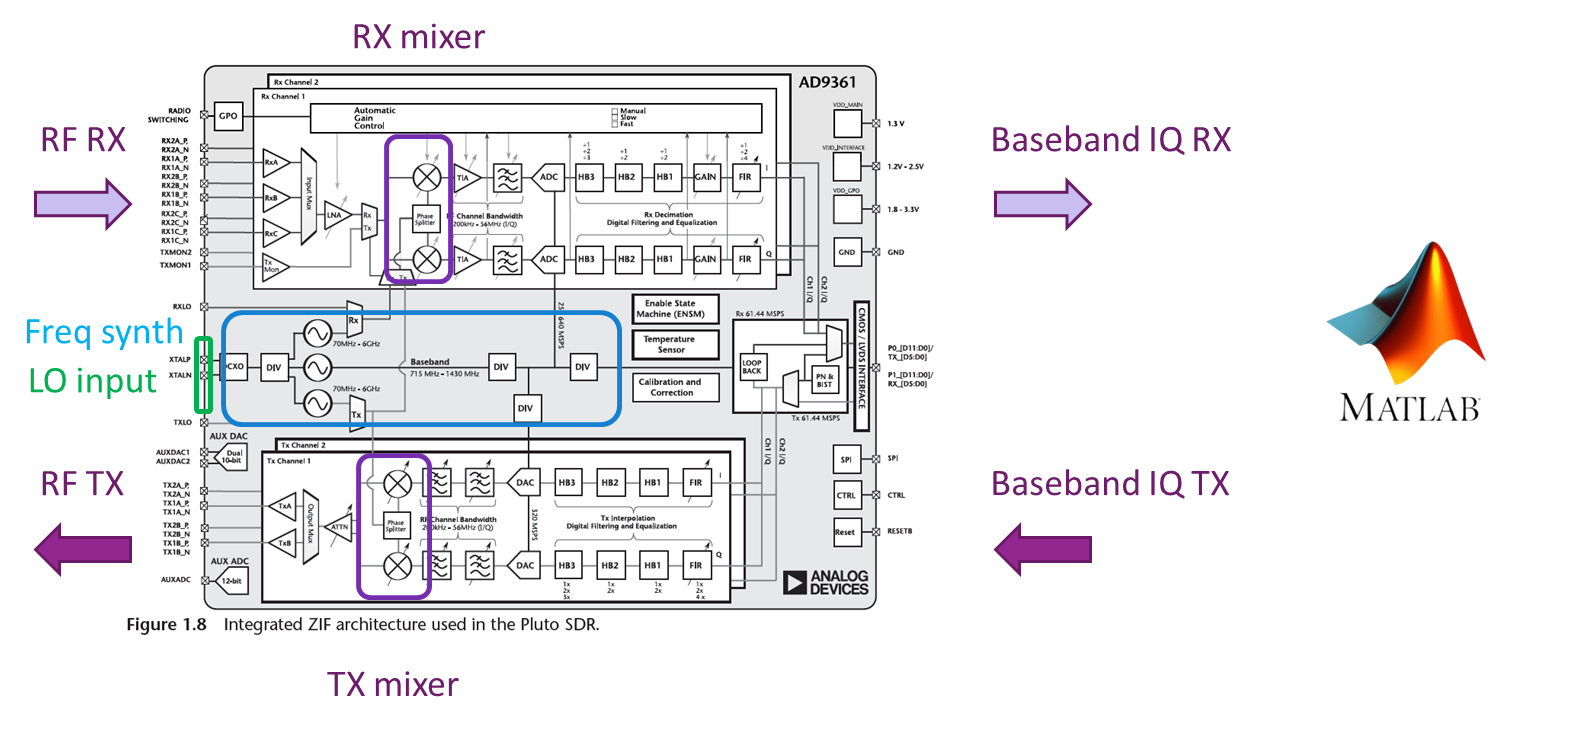

Similar to the initial SDR lab, set the parameters and create the TX and RX objects.  Observe that we can set the carrier frequency, fc.  Here, we use a carrier frequency corresponding to a band in the unlicensed spectrum, where you are allowed to transmit without permission.

% TODO:  Set parameters
% Set to true for loopback, else set to false
loopback = true;  

% Select to run TX and RX
runTx = true;
runRx = true;

% clear previous instances
clear sdrtx sdrrx

% Parameters
fsamp = 10e6;  % Sample rate in Hz.
fc = 2.4e9;  % Carrier frequency in Hz.  This is an unlicensed band that you can use

% Run the creation function
[sdrtx, sdrrx] = plutoCreateTxRx(createTx = runTx, createRx = runRx, loopback = loopback, ...
    nsampsFrame = nsamp, sampleRate = fsamp, centerFrequency = fc);

The Pluto SDR expects signals where I and Q components are in the range [-1,1].  We will create a simple scaled version with the following command.

% Create a scaled version of x
xs = x/max(abs(x));


Now, we will set the TX to repeatedly transmit the signal

% Clear the previous transmissions and transmit xs
if runTx
    sdrtx.release()
    sdrtx.transmitRepeat(xs);
end

We will now the RX to capture the samples:

if runRx 
    % TODO: Capture 2*nsamp samples and store in y
    %   y = sdrrx.capture(...);  
 

    % Scale the samples and convert to floating point
    fullScale = 2^12;
    y = single(y)/fullScale;

end


Plot the `abs(y)` vs. time in micro-seconds.  Since we have captured two frames, you  should see two copies of the transmitted signal, one after the other.  But, there will be some differences:

- The RX signal will appear at an arbitrary time offset since the sampling is not synchronized with the receiver

- The RX signal will have a dfferent amplitude since the channel and RX sub-system have gain

- The RX signal will have a time-varying phase due to carrier frequency offset.  

% TODO:
%   plot(...);



In the subsequent labs, we will show how to synchronize the receiver in time and frequency and compensate for the gain.